# Main

clc, clear;
% Look at moving average for each variable (mean). Can add standard
% deviation. Look at minimum and max accel and orientation
% Break the data up into chunks

%https://uk.mathworks.com/help/signal/ug/human-activity-recognition-using-signal-feature-extraction-and-machine-learning.html
%Look into the link above for activity recognition etc instead of what I
%have done


## Preparing Specific Data For Step Counter

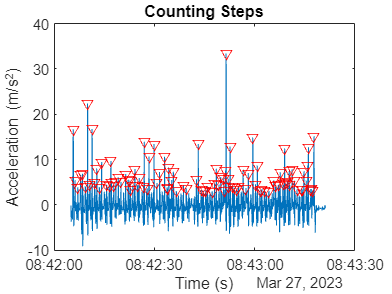


% Loads mat file into workspace and stores its data
fileName = "Step18.mat";
fileData = openFile(fileName);
walk_dataAccel = fileData.Acceleration;
walk_dataOrien = fileData.Orientation;
clear fileData fileName;

% Loads mat file into workspace and stores its data (For Step Counter)
fileName = "Sitting1.mat";
fileData = openFile(fileName);
sit_dataAccel = fileData.Acceleration;
sit_dataOrien = fileData.Orientation;
clear fileData fileName;

fileName = "run1.mat";
fileData = openFile(fileName);
run_dataAccel = fileData.Acceleration;
run_dataOrien = fileData.Orientation(1:end-1,:);
clear fileData fileName;


fileName = "Drive1.mat";
fileData = openFile(fileName);
drive_dataAccel = fileData.Acceleration;
drive_dataOrien = fileData.Orientation;
clear fileData fileName;

fileName = "stairs3.mat";
fileData = openFile(fileName);
stair_dataAccel = fileData.Acceleration;
stair_dataOrien = fileData.Orientation;
clear fileData fileName;

% Smooth out data (For Step Counter)
[walk_dataAccel, walk_dataOrien] = DataClean(walk_dataAccel, walk_dataOrien);
[sit_dataAccel,sit_dataOrien] = DataClean(sit_dataAccel, sit_dataOrien);
[run_dataAccel,run_dataOrien] = DataClean(run_dataAccel, run_dataOrien);
[drive_dataAccel,drive_dataOrien] = DataClean(drive_dataAccel, drive_dataOrien);
[stair_dataAccel,stair_dataOrien] = DataClean(stair_dataAccel, stair_dataOrien);

%Step Counter Function
stepCount = steps(walk_dataAccel);

fprintf('Number of Steps: %.15g', stepCount);

Number of Steps: 102

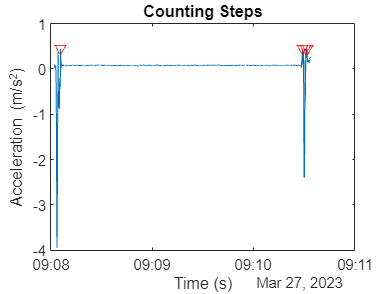

clear stepCount;

stepCount = steps(sit_dataAccel);

fprintf('Number of Steps: %.15g', stepCount);

Number of Steps: 4

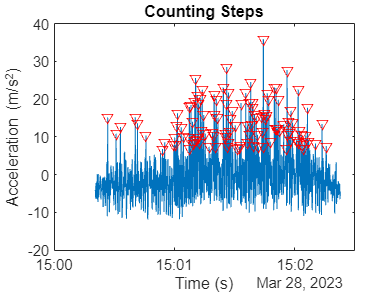

clear stepCount;

stepCount = steps(run_dataAccel);

fprintf('Number of Steps: %.15g', stepCount);

Number of Steps: 112

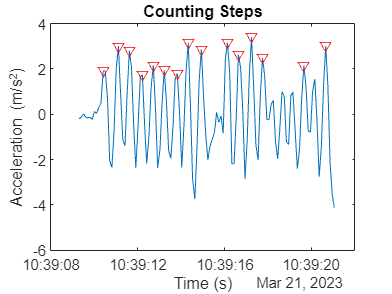

clear stepCount;

stepCount = steps(stair_dataAccel);

fprintf('Number of Steps: %.15g', stepCount);

Number of Steps: 15

clear stepCount;

clear;




## Preparing Data For Classification

% ALL THE DATA BEING USED FOR HUMAN ACTIVITY CLASSIFIER
fileName = "Step*.mat";
fileDatas = openMultiFile(fileName);
stepData = fileDatas;
clear fileName fileDatas;

fileName = "stairs*.mat";
fileDatas = openMultiFile(fileName);
stairData = fileDatas;
clear fileName fileDatas;

fileName = "Drive*.mat";
fileDatas = openMultiFile(fileName);
driveData = fileDatas;
clear fileName fileDatas;

fileName = "run*.mat";
fileDatas = openMultiFile(fileName);
runData = fileDatas;
clear fileName fileDatas;

fileName = "Sitting*.mat";
fileDatas = openMultiFile(fileName);
sitData = fileDatas;
clear fileName fileDatas;
% Extract Features from timetables (Mean)


featureData = extractFeat(stepData);
stepData= featureData;
clear featureData;
Classification = categorical(repmat("Walking",height(stepData),1));
stepData = addvars(stepData,Classification);
% stepData = rmmissing(stepData, 'DataVariables',{'Xaccel', 'Yaccel','Zaccel','Xstd', 'Ystd', 'Zstd'});

clear  Classification;


featureData = extractFeat(stairData);
stairData= featureData;
clear featureData;
Classification = categorical(repmat("Stairs",height(stairData),1));
stairData = addvars(stairData,Classification);
% stairData = rmmissing(stairData, 'DataVariables',{'Xaccel', 'Yaccel','Zaccel','Xstd', 'Ystd', 'Zstd'});
clear Classification;


featureData = extractFeat(driveData);
driveData= featureData;
clear featureData;
Classification = categorical(repmat("Driving",height(driveData),1));
driveData = addvars(driveData,Classification);
% driveData = rmmissing(driveData, 'DataVariables',{'Xaccel', 'Yaccel','Zaccel','Xstd', 'Ystd', 'Zstd'});
clear Classification;


featureData = extractFeat(runData);
runData= featureData;
clear featureData;
Classification = categorical(repmat("Running",height(runData),1));
runData = addvars(runData,Classification);
% runData = rmmissing(runData, 'DataVariables',{'Xaccel', 'Yaccel','Zaccel','Xstd', 'Ystd', 'Zstd'});
clear Classification;


featureData = extractFeat(sitData);
sitData= featureData;
clear featureData;
Classification = categorical(repmat("Sitting",height(sitData),1));
sitData = addvars(sitData,Classification);
% sitData = rmmissing(sitData, 'DataVariables',{'Xaccel', 'Yaccel','Zaccel','Xstd', 'Ystd', 'Zstd'});
clear Classification;

completeData = vertcat(stepData, stairData, driveData, runData, sitData);
completeData = timetable2table(completeData);
clear driveData runData sitData stairData stepData;


cv= cvpartition(size(completeData,1),'Holdout', 0.3);
idx = cv.test;
dataTrain = completeData(~idx,:);
dataTest = completeData(idx,:);

dataTrain = sortrows(dataTrain, "Timestamp");  
dataTest = sortrows(dataTest, "Timestamp");
save('dataTrain.mat', "dataTrain");
save('dataTest.mat', "dataTest");
dataTrain = removevars(dataTrain,{'Timestamp'});
dataTest = removevars(dataTest,{'Timestamp'});

% % Partition data to 30% to see if it plays ball
% plot(dataTest.Timestamp, dataTest.Xaccel)
% legend(unique(dataTest.Classification))

clear completeData idx cv;